# LAB3 MATLAB Programming

李志颖 12210309  夏琮杰12210520

## Introduction

In this lab assignment, we learned about：

1.Usage and scenarios of fft() and ifft() functions in MATLAB

2.The concept of algorithmic time complexity

3.Try to call the above functions to analyse the signal in the frequency domain.

4.Understand the effect of filters on signals

5.Compare the time impact of using different algorithmic strategies to deal with real-world problems.

## Results and Analysis

## 3.8

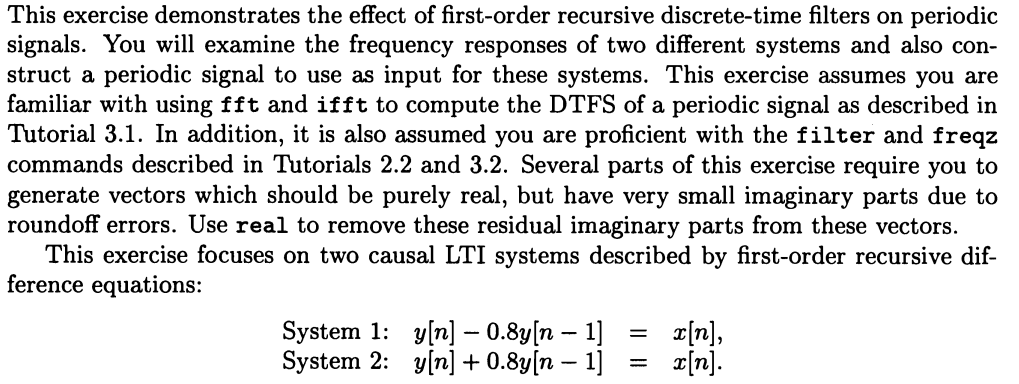

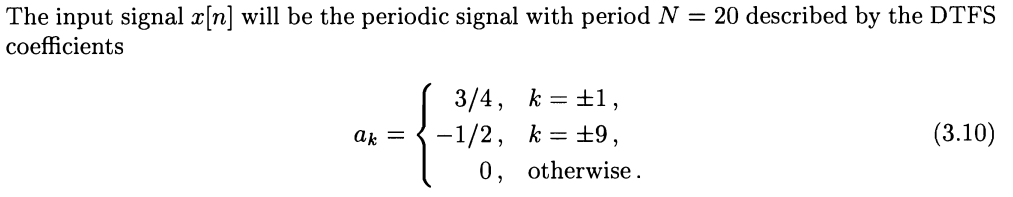

### (a)

### 

In Matlab, the coefficients at the output and input of the system are recorded using ai, bi, respectively.For the system in this question , we have a1=[1 -0.8],a2=[1 0.8],b1=b2=1

%System 1 
a1=[1 -0.8];
b1=1;
y1=filter(b1,a1,x);

%System 2 
a2=[1 0.8];
b2=1;
y2=filter(b2,a2,x);


### (b)

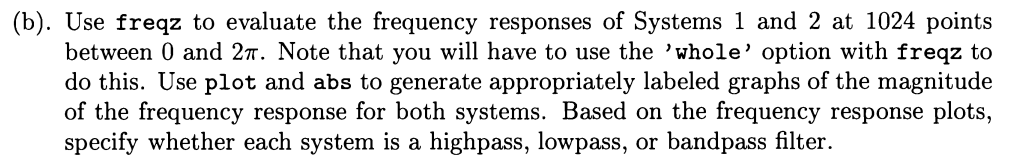

n=1024

n=1024

n = 1024

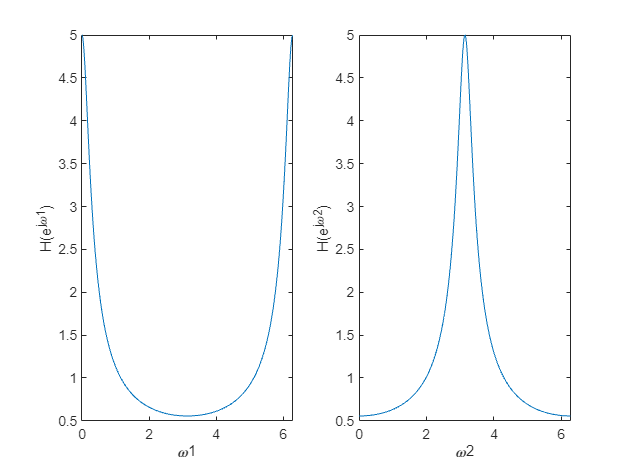


%System 1 
a1=[1 -0.8];
b1=1;
[H1, Omega1]=freqz(b1,a1,n,'whole');
subplot(1,2,1);
plot(Omega1,abs(H1));
xlabel('\omega1');ylabel('H(e^{j\omega1})');


%System 2 
a2=[1 0.8];
b2=1;
[H2, Omega2]=freqz(b2,a2,n,'whole');
subplot(1,2,2);
plot(Omega2,abs(H2));
xlabel('\omega2');ylabel('H(e^{j\omega2})');

From the image, system 1 is a low pass filter and system 2 is a high pass filter.

### (C)

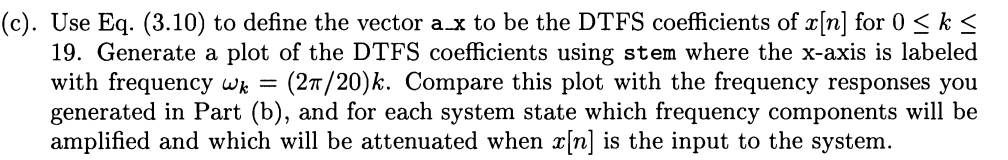

Create the vector a_x and graph it

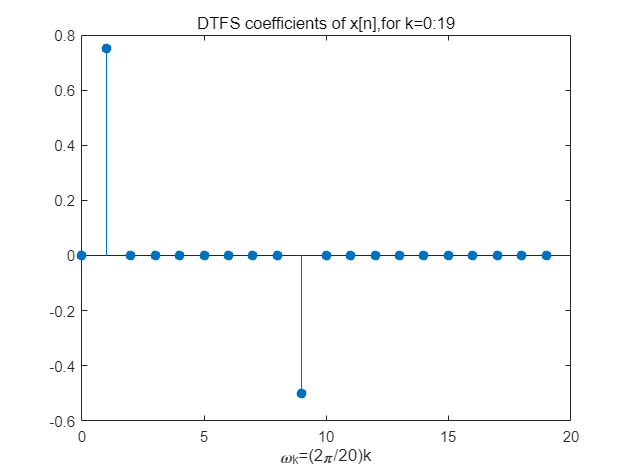

clear; clc; close all;
a_x = zeros(1, 20);
a_x(2) = 3 /4;
a_x(10) = -0.5;
stem(0:19, a_x, 'filled');
title('DTFS coefficients of x[n],for k=0:19');
xlabel('\omega_k=(2\pi/20)k');

System 1 will amplify component k=1 and attenuate component k=9. System 2 will do the opposite..

### (d)

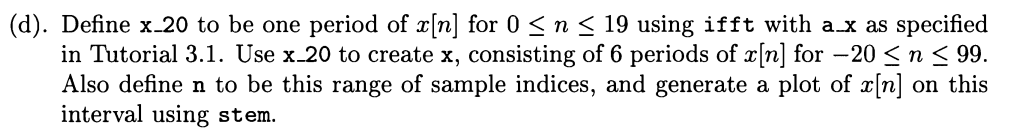

Use the ifft function to represent x_20, then use the repmat function to record the value of x over multiple cycles for the graph.

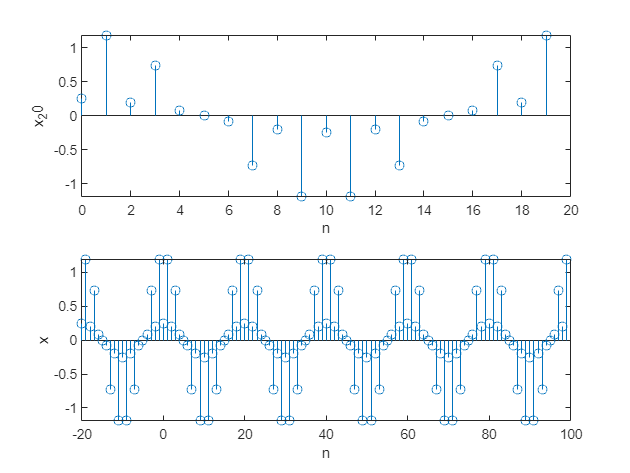

x_20 = ifft(a_x) * length(a_x);
n = -20: 99;

%plot;
subplot(2,1,1);
stem(0:19,real(x_20));
xlabel('n');ylabel('x_20');

x=real(repmat(x_20,1,6));
subplot(2,1,2);
stem(n,x);
xlabel('n');
ylabel('x');

### (e)

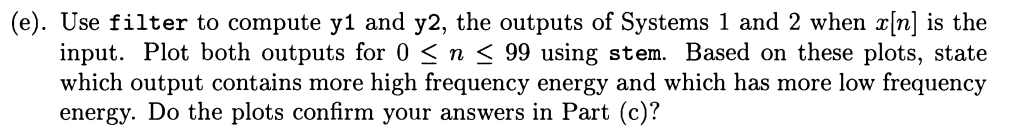

Use the filter function to obtain the output signals y1, y2 and graph them.

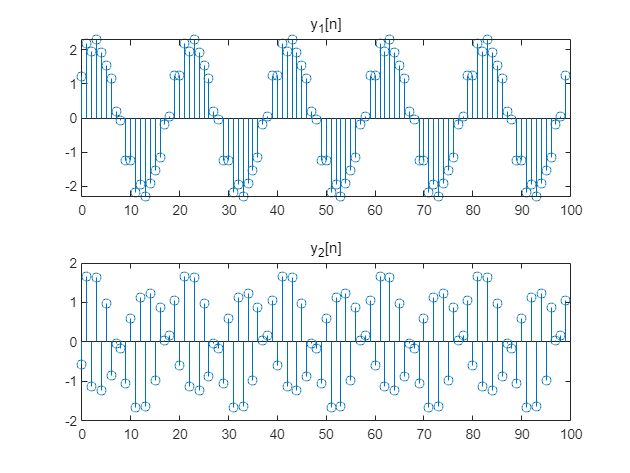

clear; clc; close all;
a_x = zeros(1, 20);
a_x(2) = 3 /4;
a_x(10) = -0.5;
x_20 = ifft(a_x) * length(a_x);
x=real(repmat(x_20,1,6));
%System 1 
a1=[1 -0.8];
b1=1;
y1=filter(b1,a1,x);

%System 2 
a2=[1 0.8];
b2=1;
y2=filter(b2,a2,x);
n=-20:99;
subplot(2, 1, 1);
stem(n, y1);
xlim([0, 100]);
title('y_1[n]');
subplot(2, 1, 2);
stem(n, y2);
xlim([0, 100]);
title('y_2[n]');

y1 has more low frequency energy. y2 has more high frequency energy. It confirmed the answers in part c. 

### (f)

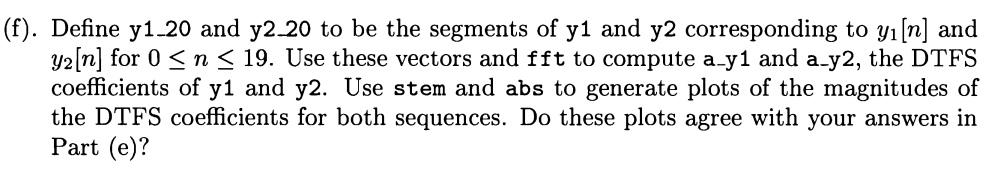

According to the question, take a one period y signal and obtain its Fourier series coefficients by fft function and make a graph.

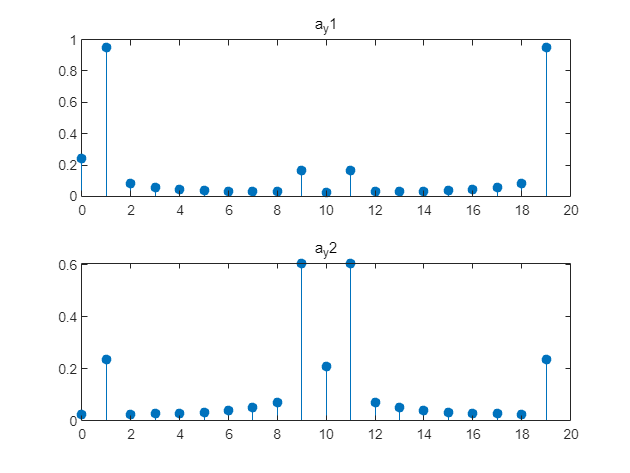

y1_20 = y1(1:20);
y2_20 = y2(1:20);
a_y1 = fft(y1_20) / length(y1_20);
a_y2 = fft(y2_20) / length(y2_20);

subplot(2, 1, 1);
stem(0:19, abs(a_y1), 'filled');
title('a_y1');
subplot(2, 1, 2);
stem(0:19, abs(a_y2), 'filled');
title('a_y2');

Comparison with the Fourier level coefficient plots of the input signals reveals that the high frequency component is suppressed after system 1 and the low frequency component is suppressed after system 2.The plots agreed with the answers in part e.

## 3.10

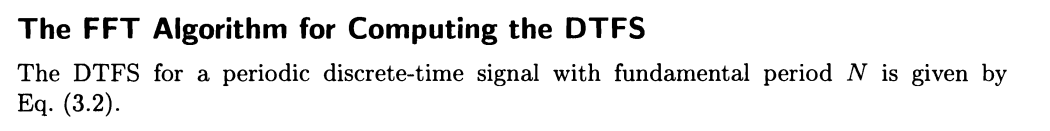

### (a)

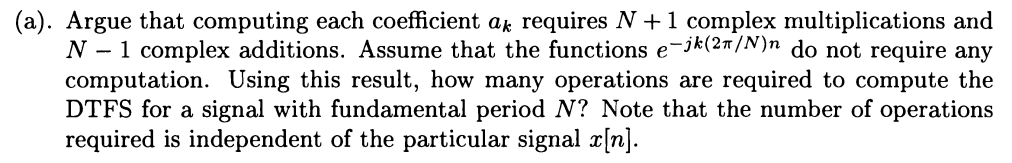

N+1 complex multiplications for computing a0 and aN/2;

2(N-1) complex multiplications for computing the remaining coefficients;

N-1 complex additions for computing all coefficients;

So, the total number of operations required to compute the DTFS is   N+1+2(N-1)+N-1 = **4N-2.**

### (b)

                 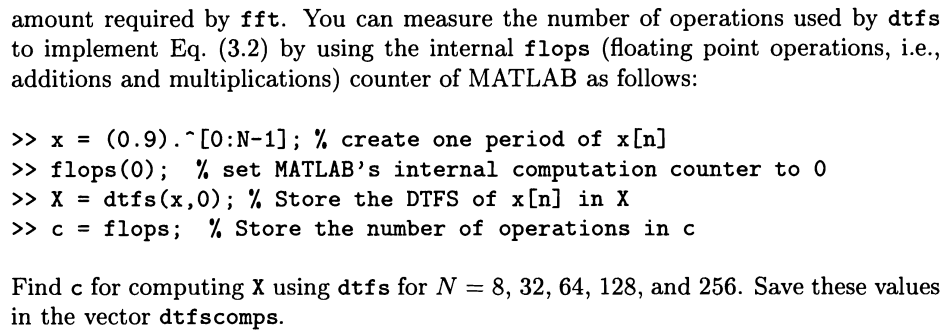

Since the new version of matlab removes the flop function, we use tic,toc to computing X using dtfs and fft for N=8,32,64,128,and 256. save them in the dtfscomps and fftcomps

clear; clc; close all;
N = [8, 32, 64, 128, 256]; 
dtfscomps = zeros(1, length(N)); 
fftcomps = zeros(1, length(N));
for i = 1:length(N)
    x = (0.9).^(0:N(i)-1); 
    tic; 
    dtfs(x,0); 
    c1 = toc; 
    dtfscomps(i) = c1; 
    tic;
    fft(x) / 5; 
    c2=toc;
    fftcomps(i) = c2; 
end
dtfscomps

dtfscomps = 1.0e-03 *

    0.2425    0.0507    0.0832    0.0412    0.1117


### (c)

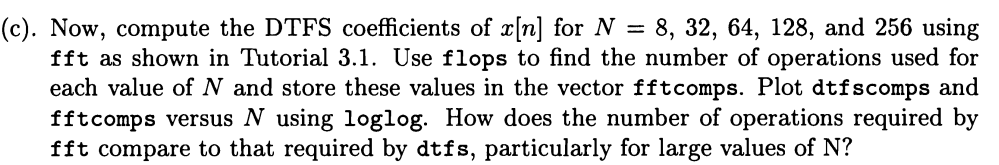

plot 

fftcomps

fftcomps = 1.0e-03 *

    0.1562    0.0276    0.0265    0.0241    0.1265


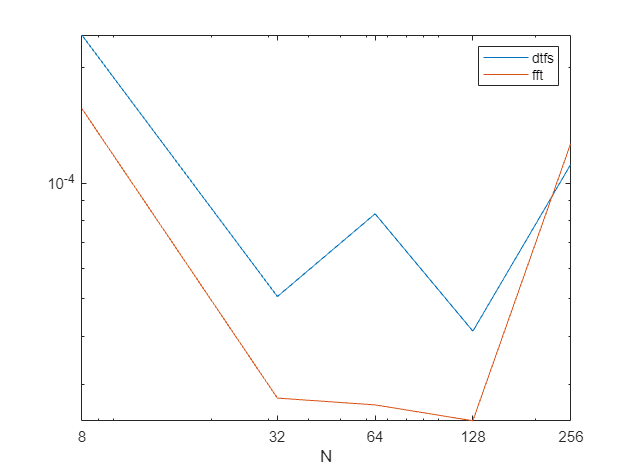


figure;
loglog(N,dtfscomps);
xticks(N);
hold on;
loglog(N,fftcomps);
legend('dtfs','fft');
xlabel('N');

### (d)

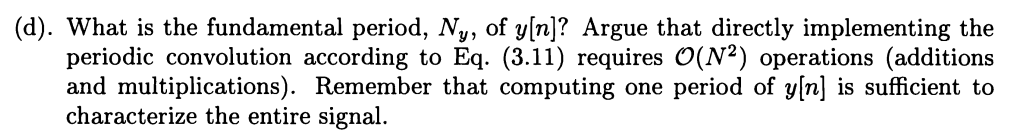

The fundamental period , N_y, of y[n] is N;


$$y\left\lbrack n+N\right\rbrack =\sum_{r=0}^{N-1} x\left\lbrack r\right\rbrack h\left\lbrack n+N-r\right\rbrack =\sum_{r=0}^{N-1} x\left\lbrack r\right\rbrack h\left\lbrack n-r\right\rbrack =y\left\lbrack n\right\rbrack$$


n is the peiod of y[n], and the fundamental period of h[n].

### (e)

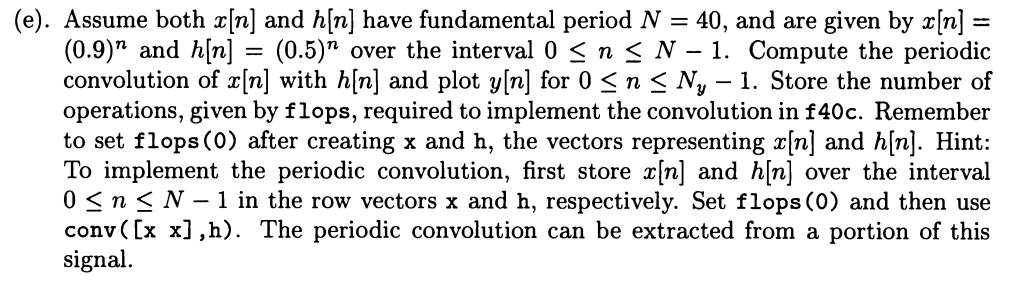

clear; clc; close all;
N = 40; 
x = (0.9).^(0:N-1); 
h = (0.5).^(0:N-1); 
n = 0+0:(2*N-1)+(N-1);
tic;
y = conv([x x], h);
f40c = toc;
f40c

f40c = 0.0015

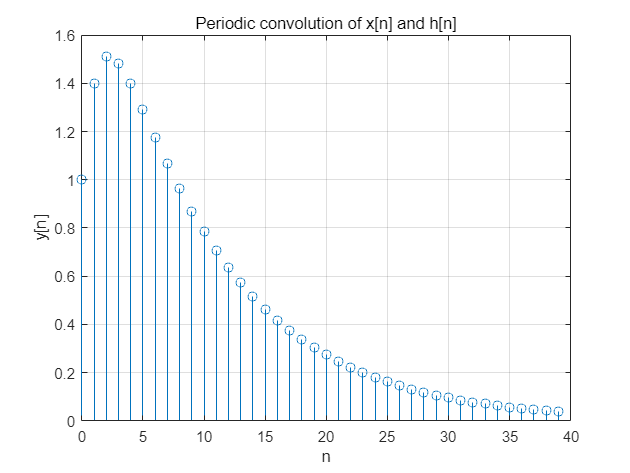

stem(n(1:N), y(1:N)); 
xlabel('n'); ylabel('y[n]'); 
title('Periodic convolution of x[n] and h[n]');
grid on; 

### (f)

same as (e)

clear; clc; close all;
N = 80; 
x = (0.9).^(0:N-1); 
h = (0.5).^(0:N-1); 
n = 0+0:(2*N-1)+(N-1);
tic;
y = conv([x x], h);
f80c = toc;

f80c = 0.0018

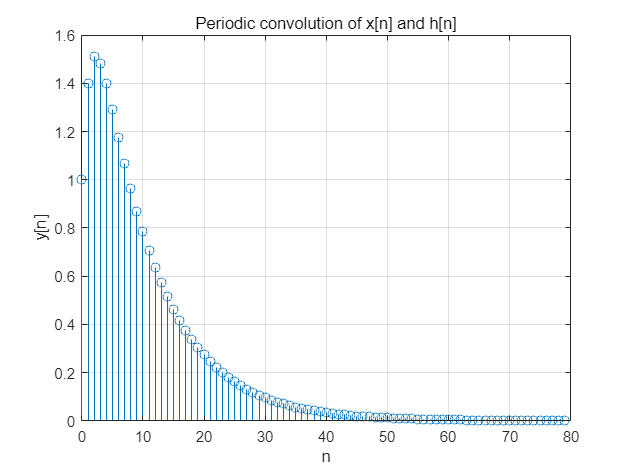

f80c
stem(n(1:N), y(1:N)); 
xlabel('n'); ylabel('y[n]'); 
title('Periodic convolution of x[n] and h[n]');

grid on; 

### (g)

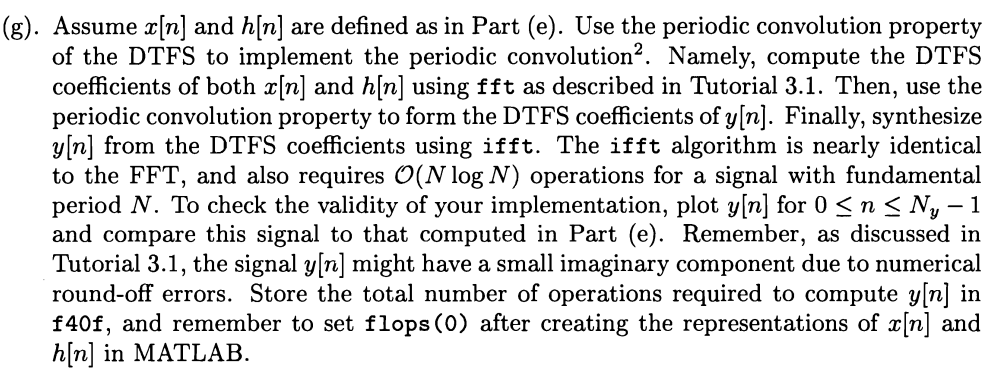

clear; clc; close all;
N = 40; 
x = (0.9).^(0:N-1); 
h = (0.5).^(0:N-1); 
n = 0+0:(2*N-1)+(N-1);
tic;
X = fft(x) / N;
H = fft(h) / N; 
Y = N.*X .* H; 
y = ifft(Y) * N; 
f40f = toc; 
f40f

f40f = 0.0043

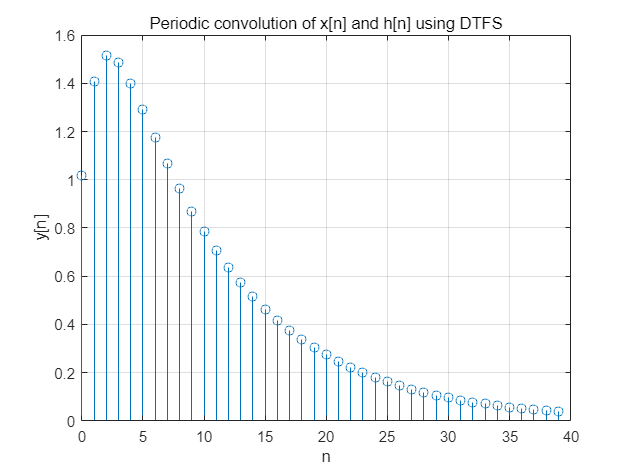

stem(n(1:N),y(1:N));
xlabel('n'); ylabel('y[n]'); 
title('Periodic convolution of x[n] and h[n] using DTFS');
grid on; 

### (h)

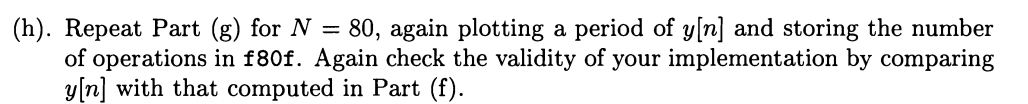

same as (g)

clear; clc; close all;
N = 80; 
x = (0.9).^(0:N-1); 
h = (0.5).^(0:N-1); 
n = 0+0:(2*N-1)+(N-1);
tic;
X = fft(x) / N;
H = fft(h) / N; 
Y = N.*X .* H; 
y = ifft(Y) * N; 
f80f = toc; 
f80f

f80f = 0.0047

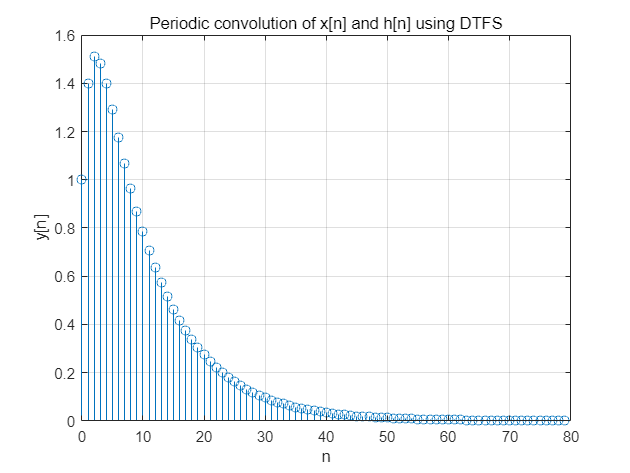

stem(n(1:N),y(1:N));
xlabel('n'); ylabel('y[n]'); 
title('Periodic convolution of x[n] and h[n] using DTFS');
grid on; 

### (i)

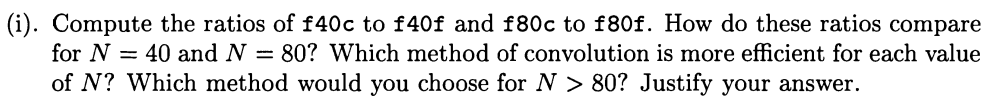

clear; clc; close all;
f40c=0.0015; f80c=0.0018;f40f=0.0043;f80f=0.0047;
ratio_40=f40c / f40f;
ratio_80=f80c / f80f;
ratio_40

ratio_40 = 0.3488

ratio_80

ratio_80 = 0.3830

these ratios increase as N increases, which means that the difference in efficiency between the two methods becomes more significant for larger values of N.

Therefore, the method of convolution that is more efficient for each value of N is the one that uses the periodic convolution property of the DTFS

This method would also be the preferred choice for N > 80

## Function

function X = dtfs(x, k)
N = length(x); 
if nargin < 2 
    k = 0:N-1; 
end
X = zeros(1, length(k));
for i = 1:length(k) 
    n = 0:N-1; 
    X(i) = sum(x .* exp(-1j * 2 * pi * k(i) * n / N)) / N; 
end
end


## Experience

exercise figure

12210309 李志颖

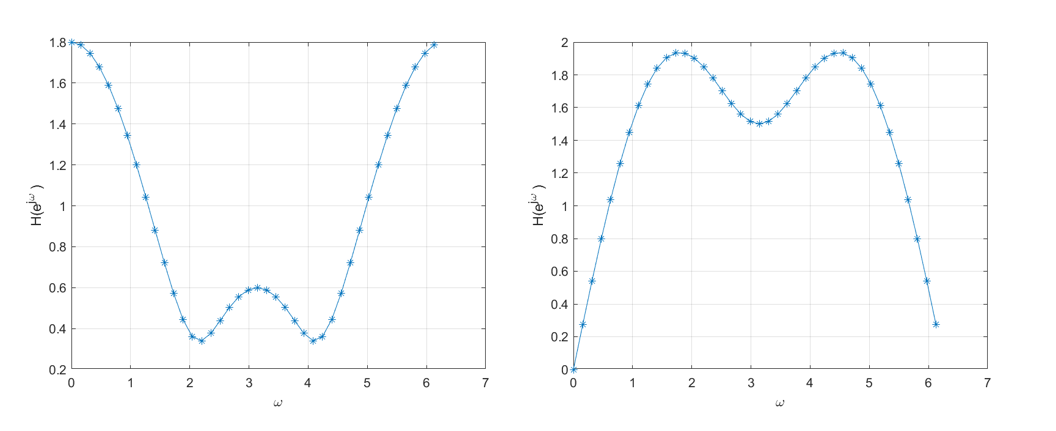

12210520 夏琮杰

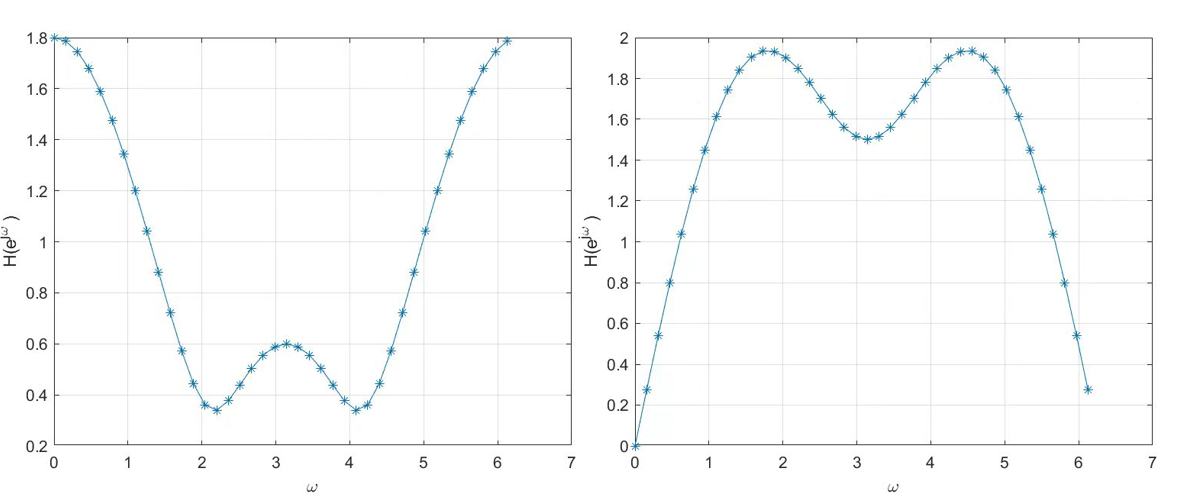

1.We have learnt about the use of the fft(),which can be used to decompose a signal: converting a signal into its Fourier series representation. 

2.We have learnt about the use of the ifft() ,which performs the synthesis of the signal: it represents a series of signals corresponding to the Fourier series coefficients.

3.We learnt how filters work: signals of different frequencies are amplified or reduced in a specific way to achieve the effects of "high pass", "low pass" and "band pass".

4.When choosing an algorithm to solve a problem, it is important to consider the time complexity and other relevant parameters while satisfying the functionality to achieve the most efficient use of the code to complete the task.

5.We realize that different systems do have different filtering effects